## `GC and RL Problem`` - Example 01`

`Author: aleksander.grm@fpp.uni-lj.si, 20/02/2020`

#### `First Problem:`

`Inputs:`

- departure position: $P_1=(\varphi_1,\lambda_1)$

- arrival position: $P_2=(\varphi_2,\lambda_2)$

`Outputs:`

- Course: $\omega$

- Distance: $D$

fi_1 = [45,33.6,0]; % [deg, min, sec]
la_1 = [15,47.2,0]; % [deg, min, sec]
fi_2 = [37,17.8,0]; % [deg, min, sec]
la_2 = -[102,27.4,0]; % [deg, min, sec]

[w1_gc, d_gc, fiv_gc, lav_gc] = GC_data(fi_1,la_1,fi_2,la_2);
fiv = deg2dms(fiv_gc);
lav = deg2dms(lav_gc);

[w1_rl, d_rl] = RL_P1_data(fi_1,la_1,fi_2,la_2);

fprintf('P1: fi=%+d\xB0 %.2f\x27, la=%+d\xB0 %.2f\x27', fi_1(1), fi_1(2)+fi_1(3)/60, la_1(1), la_1(2)+la_1(3)/60)

P1: fi=+45° 33.60', la=+15° 47.20'

fprintf('P2: fi=%+d\xB0 %.2f\x27, la=%+d\xB0 %.2f\x27', fi_2(1), fi_2(2)+fi_2(3)/60, la_2(1), la_2(2)+la_2(3)/60)

P2: fi=+37° 17.80', la=-102° -27.40'

fprintf('-------------------')

-------------------

fprintf('GC: w1=%.2f\xB0, d=%.2f Nm, fi_v=%+d\xB0 %.2f\x27, la_v=%+d\xB0 %.2f\x27', w1_gc, d_gc, fiv(1), fiv(2)+fiv(3)/60, lav(1), lav(2)+lav(3)/60)

GC: w1=225.32°, d=4816.02 Nm, fi_v=+60° 8.57', la_v=-19° 11.92'

fprintf('RL: w1=%.2f\xB0, d=%.2f Nm', w1_rl, d_rl)

RL: w1=264.66°, d=5330.71 Nm

fprintf('D_RL - D_GC = %.2f Nm', d_rl - d_gc)

D_RL - D_GC = 514.69 Nm

Find maxima distance difference for RL and GL

N=1000;
dfi = 10/N;
fi_b = 35;
la1 = [0,0,0];
la2 = [180,0,0];

data = zeros(2,N);
for i = 1:N
    fi = deg2dms(fi_b + i*dfi);
    [w1_gc, d_gc, fiv_gc, lav_gc] = GC_data(fi,la1,fi,la2);
    [w1_rl, d_rl] = RL_P1_data(fi,la1,fi,la2);
  
  data(:,i) = [fi_b + i*dfi, d_rl - d_gc];
end

idx = find(abs(data(2,:)-max(data(2,:))) < 1e-8);
fi_max = deg2dms(data(1,idx));
fprintf('max_Dif_dist=%.2f, max_fi=%+d\xB0 %.2f\x27',data(2,idx), fi_max(1), fi_max(2)+fi_max(3)/60)

max_Dif_dist=2273.55, max_fi=+39° 32.40'

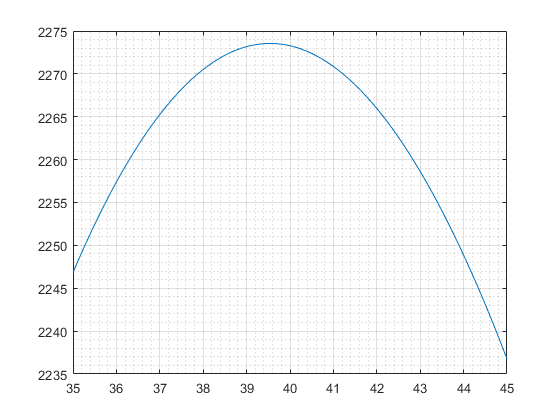


plot(data(1,:),data(2,:))
grid on
grid minor